`7% PHY4MES Computational Assignment Part B`

`% The following code was provided for the assignment,`

`% edited by Pierce Bowman, 19396911. 30 March 2023`

`% Poisson-Schrodinger Solver`

`% Iterative solver for semiconductor quantum well structures`

`% A Schenk 2015 % La Trobe University % Altered from pre-existing code for PHY5PQA Matlab assignment %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% % Code modified by David Hoxley May 2020 % more comments, tidied up layout`

`% clear workspace and plots`

clear all
disp('Hello, Josh')

Hello, Josh


`% Preset parameters-Do Not Change!`

hbar=1.06e-34; % Plancks constant [Js]
q=1.6e-19; % Elementary charge [C]
eps0=8.85e-12; % Permitivity of free space [F/m]
epsr=4; % Relative permittivity
m=0.25*9.1e-31; % Effective mass [kg],
k=8.617e-5; % Boltzmann constant [eV/K]

`%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%`

`% Calculation parameters-Change these as necessary`

`% Default values are % a=3e-11 m`

`% mu= 1`

`% T= 300`

`% Nout= 2e-9/a mesh widths`

`% Nw=  13 nm`

`% E_out= 4 eV`

a=3e-11; % mesh size [m] (Default is 30 pm)
mu=1; % Fermi level [eV]
T=300; % Temperature [K]
Nout=round(2e-9/a) % Outer passivating layer in mesh units

Nout = 67

Nw=round(13e-9/a) % Well width [mesh widths] 

Nw = 433

E_out=4; % Energy Height of outer barrier
% Vg=0; % Gate potential (not used for this calculation)

`%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     `

`%More parameters needed for calculations. Do not change`

t0=(hbar^2)/(2*m*(a^2)*q); %Scaling factor
e0=q*a/eps0; %Scaling factor
kT=k*T; 
n0=m*kT*q/(2*pi*(hbar^2)); %2D DOS
Np=2*Nout+Nw; %layer thickness in units of mesh size

`%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% `

XX=a*1e9*[1:1:Np]; % set up the 'domain'
Ec=[E_out*ones(Nout,1);0*ones(Nw,1);E_out*ones(Nout,1)]; % creates the barrier heights

`% the following embeds the required solving the coupled schrodinger/poisson`

`% eqns into the code, solving the eqns at each mesh point. the code begins`

`% with a basic well profile, U1, then iteratively changes the profile to`

`% distort due to the charge density of present electrons. iterating until`

`% sufficienty small perturbation affect.`

T=(2*t0*diag(ones(1,Np)))-(t0*diag(ones(1,Np-1),1))-(t0*diag(ones(1,Np-1),-1));
D2=epsr*((2*diag(ones(1,Np)))-(diag(ones(1,Np-1),1))-diag(ones(1,Np-1),-1));
iD2=inv(D2);
Vg=0;
Ubdy=-4*[Vg;zeros(Np-2,1);Vg];
U0=iD2*Ubdy;
U1=1e-9*ones(Np,1);UU=U1;change=1;
while change>1e-6
    U1=U1+0.1*(UU-U1);
    [P,D]=eig(T+diag(Ec)+diag(U1));D=diag(D);
    rho=log(1+exp((mu-D)./kT)); rho=P*diag(rho)*P';
    n=2*n0*diag(rho);
    UU=U0+iD2*e0*n;
    change=max(max((abs(UU-U1))));
    U=Ec+U1;
    %disp(change)
end;
ns=1e-4*sum(sum(n.*[zeros(Nout,1);ones(Nw,1);zeros(Nout,1)]));
nn=1e-6*n./a;

`% Beginning of code made by me for the assignment questions`

`% First change E_out and see what effect this has on both the electron`

`% energy eigenvalues and the electron density of the eigenstates.`

`% Second change Nw and see what effect this has on both the electron`

`% energy eigenvalues and the electron density of the eigenstates. then compare this to the infinite well.`

`% Third alter the temperature then see what effect this has on both the electron`

`% energy eigenvalues and the electron density of the eigenstates. is this expected?`

`% Fourth change fermi level (mu) position and see what effect this has on both the electron`

`% energy eigenvalues and the electron density of the eigenstates. is this expected?`

`% Fifth change Nout, keeping nw static and see what effect this has on both the electron energy eigenvalues and the electron density of the eigenstates.`

disp('The first 5 Energy Eigenvalues are:')

The first 5 Energy Eigenvalues are:


fprintf('   %8.7f\n',D(1:5))

   0.9475433
   0.9479340
   1.0410358
   1.0834791
   1.1529766


`% Calculating electron density for the first 5 states:`

`% Ground state`

Occ_1=log(1+exp((mu-D(1))./kT)); % probability of electron occupation
Ed_1=P(:,1).*Occ_1.*P(:,1); % electron density found using the occupation probability
N_1=2*n0*Ed_1; % factoring in number of electron states, i.e.; spin effects
n1_sum=1e-4*sum(sum(N_1.*[ones(Np,1)])); % final electron number density

`% Second state`

Occ_2=log(1+exp((mu-D(2))./kT));
Ed_2=P(:,2).*Occ_2.*P(:,2);
N_2=2*n0*Ed_2;
n2_sum=1e-4*sum(sum(N_2.*[ones(Np,1)]));

`% Third state`

Occ_3=log(1+exp((mu-D(3))./kT));
Ed_3=P(:,3).*Occ_3.*P(:,3);
N_3=2*n0*Ed_3;
n3_sum=1e-4*sum(sum(N_3.*[ones(Np,1)]));

`% Fourth state`

Occ_4=log(1+exp((mu-D(4))./kT));
Ed_4=P(:,4).*Occ_4.*P(:,4);
N_4=2*n0*Ed_4;
n4_sum=1e-4*sum(sum(N_4.*[ones(Np,1)]));

`% Fifth state`

Occ_5=log(1+exp((mu-D(5))./kT));
Ed_5=P(:,5).*Occ_5.*P(:,5);
N_5=2*n0*Ed_5;
n5_sum=1e-4*sum(sum(N_5.*[ones(Np,1)]));

`% Print the densities for the first 5 states`

fprintf('\nElectron Density values for the first five states:\n')


Electron Density values for the first five states:


fprintf('   %8.7e\n',n1_sum,n2_sum,n3_sum,n4_sum,n5_sum)

   5.7384936e+12
   5.7029155e+12
   4.9590438e+11
   1.0349446e+11
   7.1653870e+09


`% Plot the the well;`

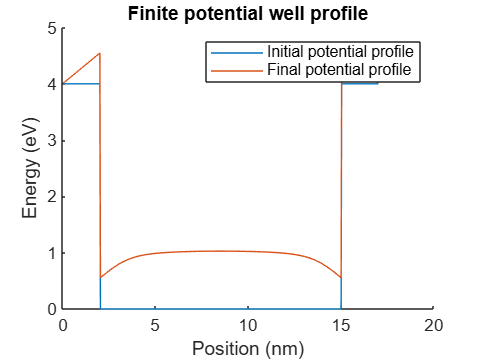

figure
hold on
plot(XX,Ec)
plot(XX,U)
title('Finite potential well profile')
legend('Initial potential profile','Final potential profile')
xlabel('Position (nm)')
ylabel('Energy (eV)')
hold off

`% Lastly, find the probability density of the finite well, is it confined to the well? Why/why not.`

`% this section of code purely for the part concerning the probability. It plots the probability densities for the first five states.`

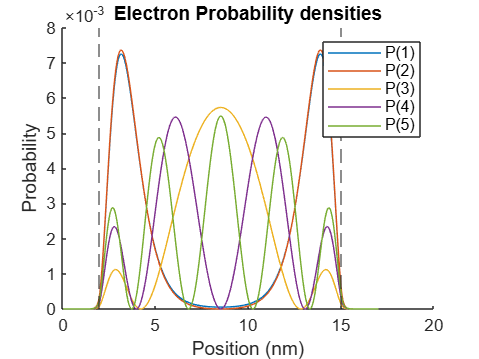

figure
hold on
title('Electron Probability densities')
plot(XX,P(:,1).^2)
plot(XX,P(:,2).^2)
plot(XX,P(:,3).^2)
plot(XX,P(:,4).^2)
plot(XX,P(:,5).^2)
xlabel('Position (nm)')
ylabel('Probability')
xline(2,'--')
xline(15,'--')
legend('P(1)','P(2)','P(3)','P(4)','P(5)')
hold off